# TAREA 2

## IE0431 Sistemas de Control - Universidad de Costa Rica, Escuela de Ingeniería Eléctrica

## Diego Alfaro Segura, C20259, grupo 01

clc
clear
close all

## Parámetros del tanque y proceso.

A = 6;                  % Área del tanque
g = 9.81;               % Gravedad

H0_v = [2.26 2.6 2.95]; % Valores de nivel de líquido del tanque 
H0 = H0_v(2);           % Punto de operación deseado del líquido en el tanque

Kvs = 0.001;            % Constante de la válvula de salida del tanque
Xvs_v = [0.4 0.5 0.6];  % Valores de apertura de válvula
Xvs0 = Xvs_v(2);        % Apertura deseada de la válvula de salida del tanque

rho = 1261;             % Densidad del líquido (agua)
ambitoSensor = 3.25;    % Ámbito de medición del sensor

## b) La ganancia del transmisor de nivel Kt.

Kt = 100/ambitoSensor;

## c) Kvc ganancia de la válvula control.

% Se calcula con la ecuación de la característica estática y Hmax, Xvsmax
Qemax = max(Xvs_v)*Kvs*sqrt(max(H0_v)*g*rho);
Kvc   = Qemax/100;

## d) Valores para simulink.

steptimeu = 100;                % El primer cambio se hace en 100 s
Qe0 = Xvs0*Kvs*sqrt(H0*g*rho);  % Se calcula con la ecuación de la característica estática y H0, Xvs0
u0 = Qe0/Kvc;                   % Punto operación del caudal de entrada en %
deltau = u0-2;                  % Cambio de -2% en U
steptimed = 3000;               % La perturbación se aplica hasta que el sistema se estacione del cambio en Qe
deltad = Xvs0-0.02;             % Cambio -0.02 en la perturbación

## e) Valor de T, K1 y K2 del modelo linealizado.

K1 =  2/(Xvs0*Kvs) * sqrt(H0/(g*rho));
K2 = -2*H0/Xvs0;
T  =  2*A/(Xvs0*Kvs) * sqrt(H0/(g*rho));

## f) Comparación de respuestas real y lineal.

tu = 6000; % Tiempo simulación
out = sim('C20259_DiegoAlfaro_G01.slx',tu); %comando para simular el DB

### i.

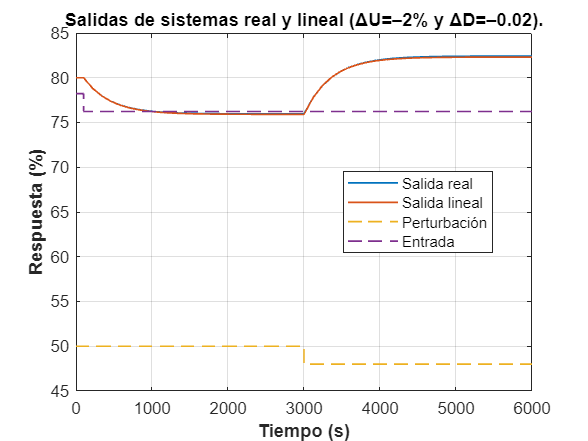

plot(out.yReal,"LineWidth",1,'DisplayName',"Salida real"); % Salida sistema real

hold on                 
plot(out.yLineal,"LineWidth",1,'DisplayName',"Salida lineal");  % Salida sistema lineal
plot(out.Xvs,"LineWidth",1,'DisplayName',"Perturbación", 'LineStyle', "--");
plot(out.qe,"LineWidth",1,'DisplayName',"Entrada", 'LineStyle', "--");

% Personalización
grid on
legend('Location','best');
title("Salidas de sistemas real y lineal (ΔU=–2% y ΔD=–0.02).");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Respuesta (%)",'FontWeight','bold');
xlim([0 6000]);
hold off

### ii.

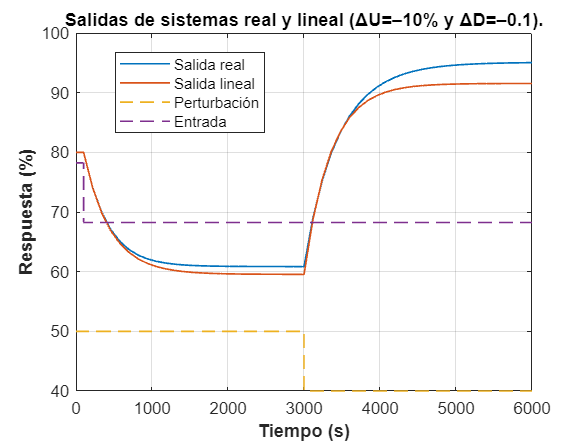

% Se cambian los deltas aplicados.
deltau = u0-10;
deltad = Xvs0-0.1;
out = sim('C20259_DiegoAlfaro_G01.slx',tu); %comando para simular el DB

plot(out.yReal,"LineWidth",1,'DisplayName',"Salida real");  % Salida sistema real

hold on                 
plot(out.yLineal,"LineWidth",1,'DisplayName',"Salida lineal");  % Salida sistema lineal
plot(out.Xvs,"LineWidth",1,'DisplayName',"Perturbación", 'LineStyle', "--");
plot(out.qe,"LineWidth",1,'DisplayName',"Entrada", 'LineStyle', "--");

% Personalización
grid on
legend('Location','best');
title("Salidas de sistemas real y lineal (ΔU=–10% y ΔD=–0.1).");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Respuesta (%)",'FontWeight','bold');
xlim([0 6000]);
hold off

## g) Curvas estáticas

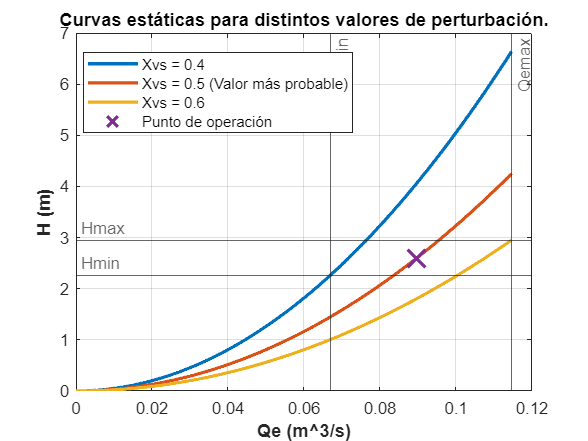

Qe = linspace(0, Qemax, 1000);
Qemin = min(Xvs_v)*Kvs*sqrt(min(H0_v)*g*rho);
H1 = 1/(rho*g) * (Qe/(Xvs_v(1)*Kvs)).^2;
H2 = 1/(rho*g) * (Qe/(Xvs_v(2)*Kvs)).^2;
H3 = 1/(rho*g) * (Qe/(Xvs_v(3)*Kvs)).^2;

plot(Qe, H1, "LineWidth",2,'DisplayName', "Xvs = 0.4");

hold on                 
plot(Qe, H2,"LineWidth",2,'DisplayName', "Xvs = 0.5 (Valor más probable)");
plot(Qe, H3,"LineWidth",2,'DisplayName', "Xvs = 0.6");
plot(Qe0, H0, 'x', 'MarkerSize', 15, "LineWidth", 2, 'DisplayName','Punto de operación');
xline(Qemax, "Label",'Qemax', 'HandleVisibility', 'off')
yline(max(H0_v), "Label",'Hmax', 'HandleVisibility', 'off', 'LabelHorizontalAlignment','left')
xline(Qemin, "Label",'Qemin', 'HandleVisibility', 'off')
yline(min(H0_v), "Label",'Hmin', 'HandleVisibility', 'off', 'LabelHorizontalAlignment','left')

% Personalización
grid on
legend('Location','best');
title("Curvas estáticas para distintos valores de perturbación.");
xlabel("Qe (m^3/s)",'FontWeight','bold');
ylabel("H (m)",'FontWeight','bold');
hold off